# Lab 2

### Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna

## Contrast i Offset

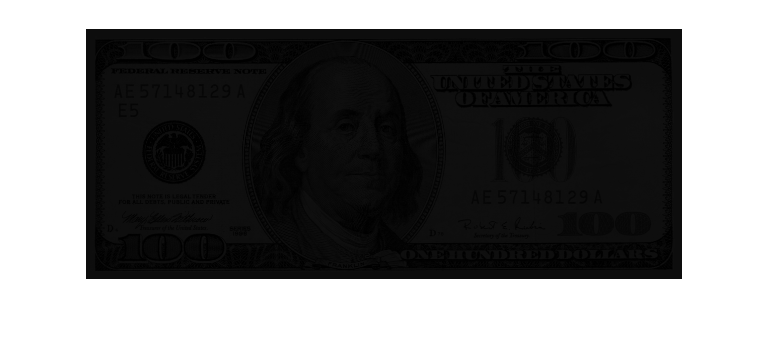

I = imread('Que_es.png');
imshow(I)

max(I(:))

ans = uint8
16

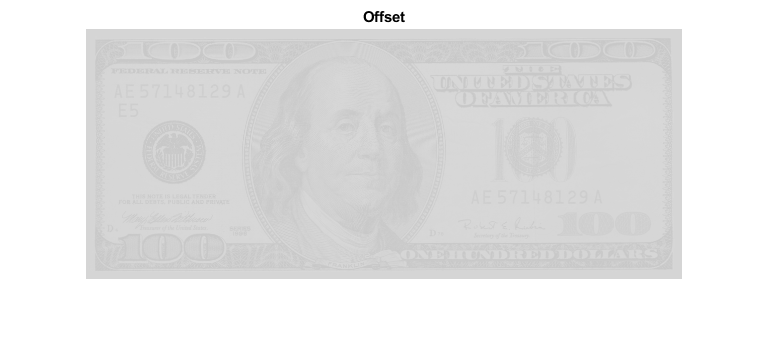

I2 = I+200;
figure,imshow(I2), title('Offset')

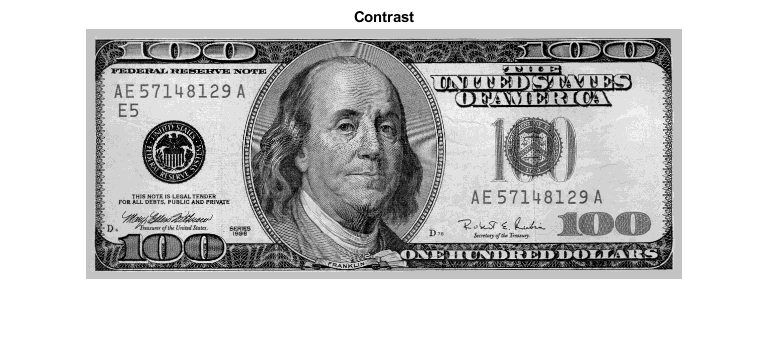

I2 = I*15;
figure, imshow(I2), title('Contrast')

## Bucle vs Operacions Matricials

[files,cols] = size(I)

files = 250

cols = 596

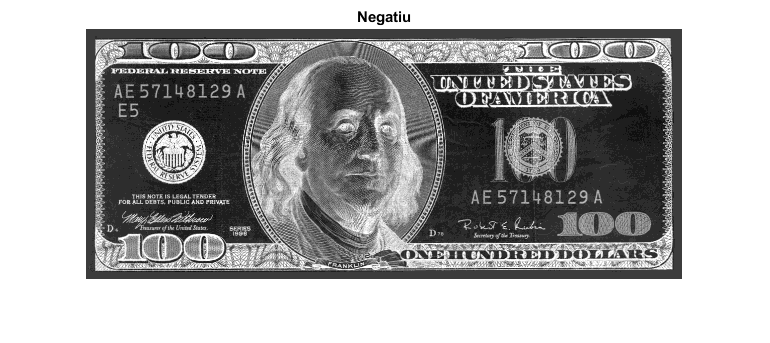

for i = 1:files
    for j = 1:cols
        I3(i,j) = 255-I2(i,j);
    end
end
figure, imshow(I3), title('Negatiu')

El codi efectuat anteriorment no té sentit del tot perquè per qüestions d'eficència podem eliminar el bucle i efectuar operacions matricials. 

I3 = 255-I2;

## Histograma 

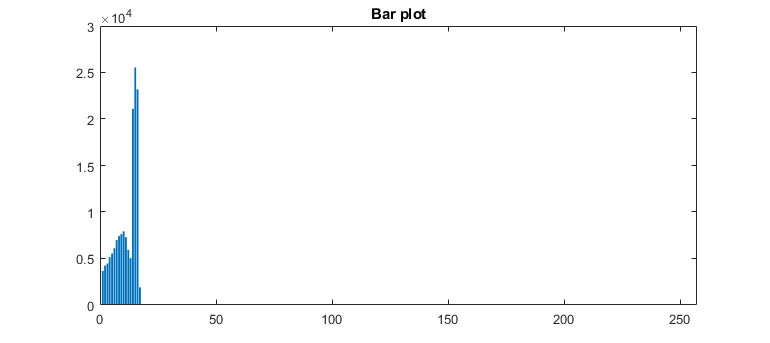

I3 = zeros(1,256);
for i = 1:files
    for j = 1:cols
        I3(I(i,j)+1) = I3(I(i,j)+1)+1;
    end
end
bar(I3), title('Bar plot')

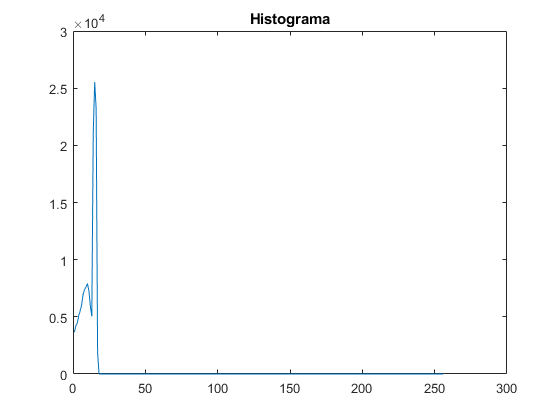

h = imhist(I);
figure,plot(h), title('Histograma');

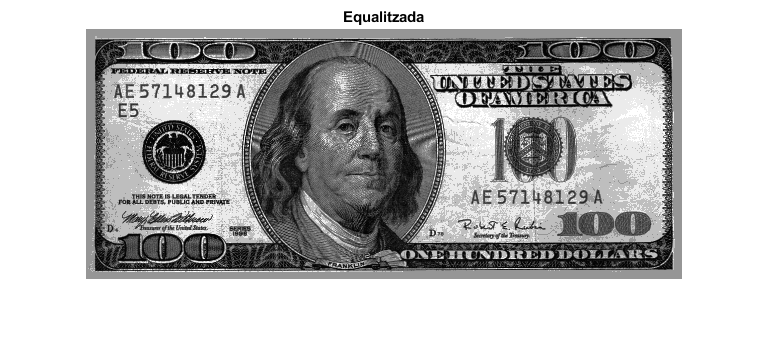

I4 = histeq(I);
figure,imshow(I4),title('Equalitzada')

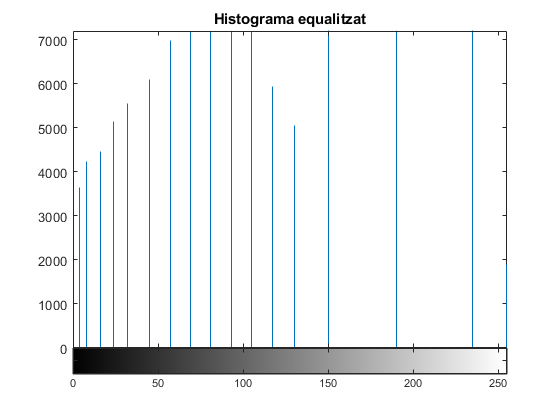

figure,imhist(I4),title('Histograma equalitzat')

## Operacions en píxels

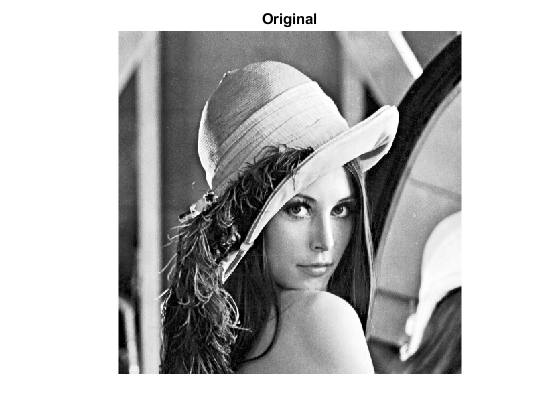

I = imread('lenna.tif');
imshow(I),title('Original')

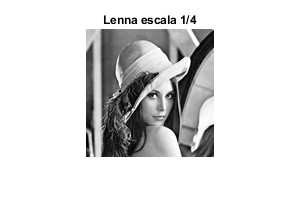

I2 = imresize(I,0.25);
figure,imshow(I2),title('Lenna escala 1/4')

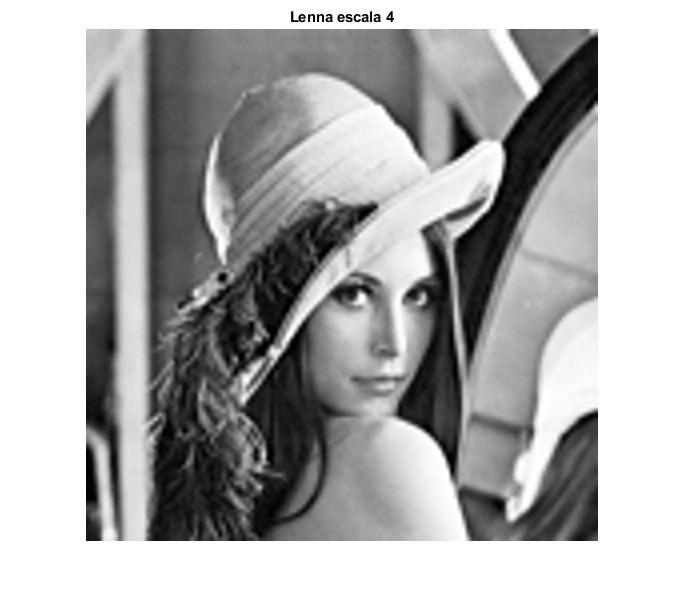

I3 = imresize(I2,4);
figure,imshow(I3),title('Lenna escala 4')

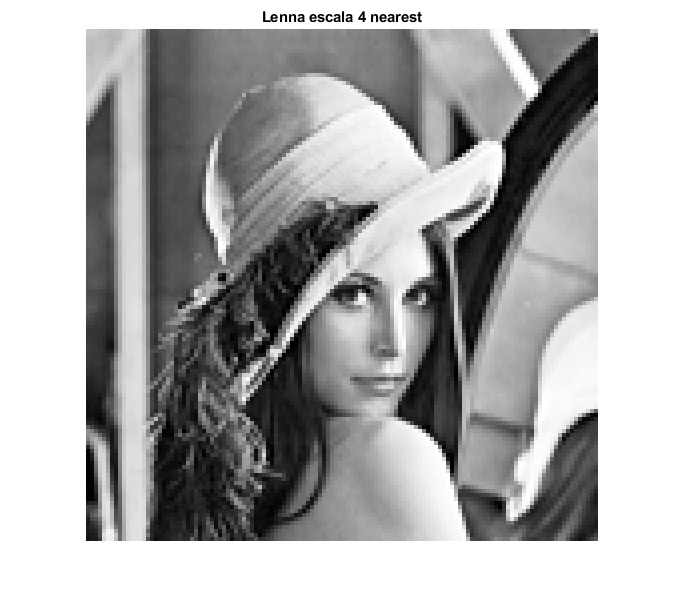

I4 = imresize(I2,4,'nearest');
figure,imshow(I4),title('Lenna escala 4 nearest')

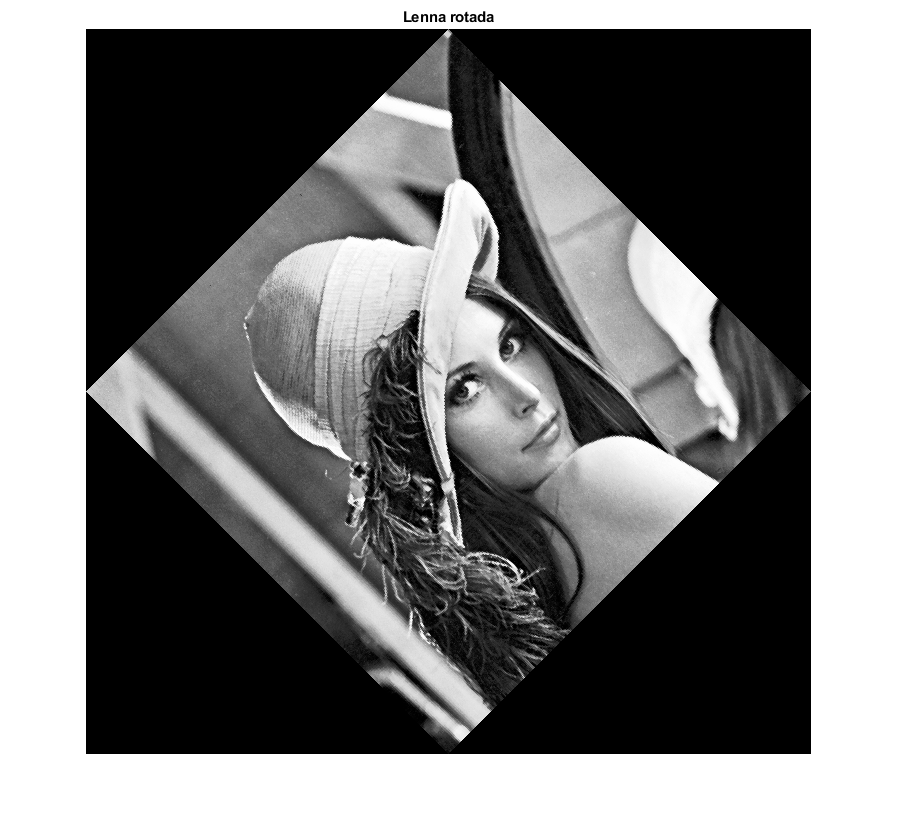

I5 = imrotate(I,45);
figure,imshow(I5),title('Lenna rotada')

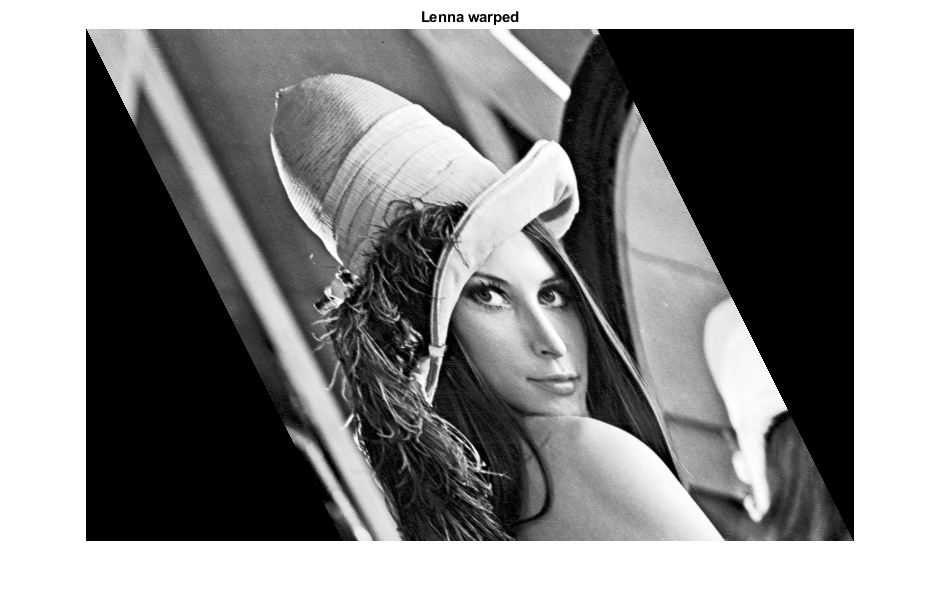


T = affine2d([1 0 0;0.5 1 0;0 0 1]);
I6 = imwarp(I,T);
figure,imshow(I6),title('Lenna warped')

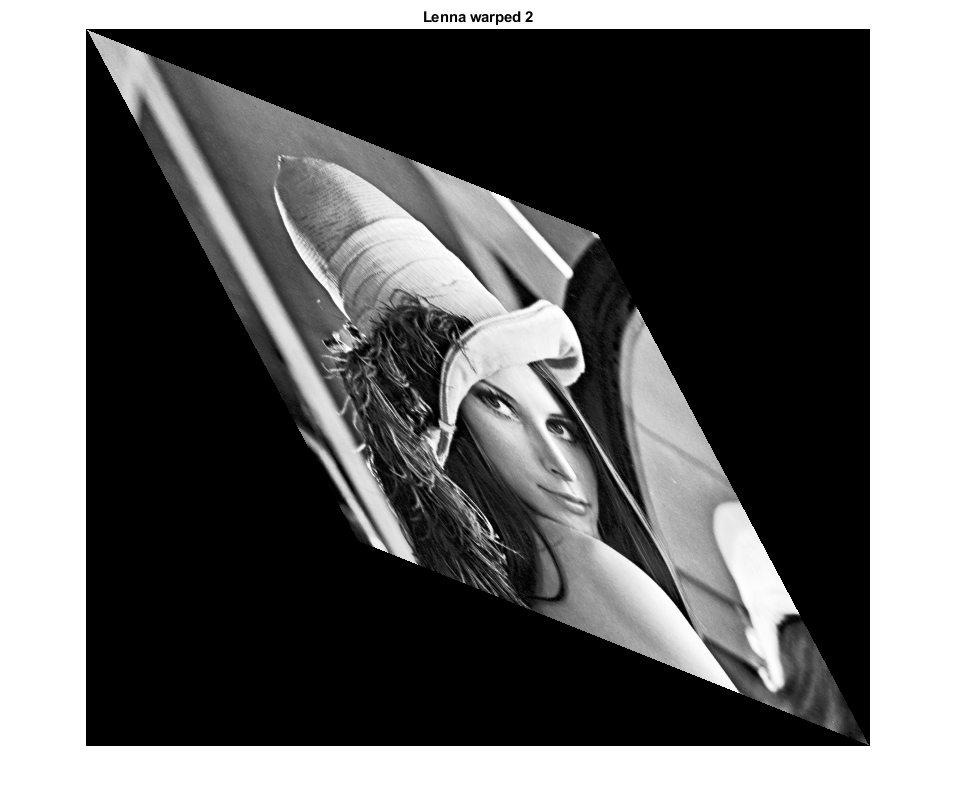



T2 = affine2d([1 0.4 0;0.53 1 0;0 0 1]);
I6 = imwarp(I,T2);
figure,imshow(I6),title('Lenna warped 2')

## Operacions amb dues imatges 

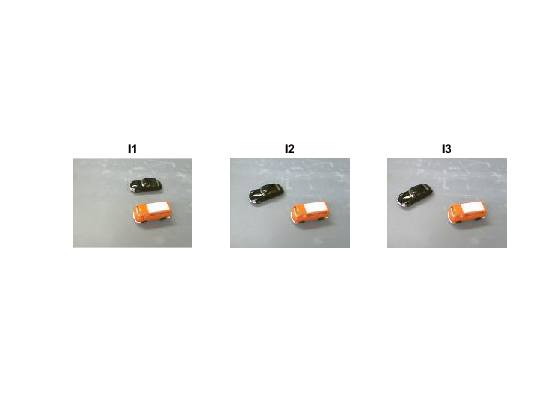

I1 = imread('toycars1.png');
I2 = imread('toycars2.png');
I3 = imread('toycars3.png');
figure, subplot(1,3,1),imshow(I1), title('I1')
subplot(1,3,2), imshow(I2), title('I2')
subplot(1,3,3),imshow(I3), title('I3')

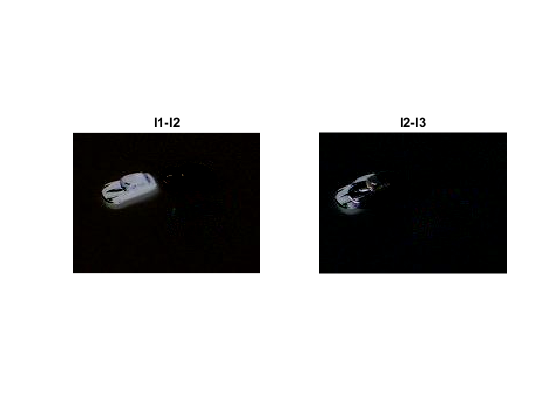

res1 = I1-I2;
res2 = I2-I3;
figure, subplot(1,2,1), imshow(res1), title('I1-I2')
subplot(1,2,2), imshow(res2), title('I2-I3')

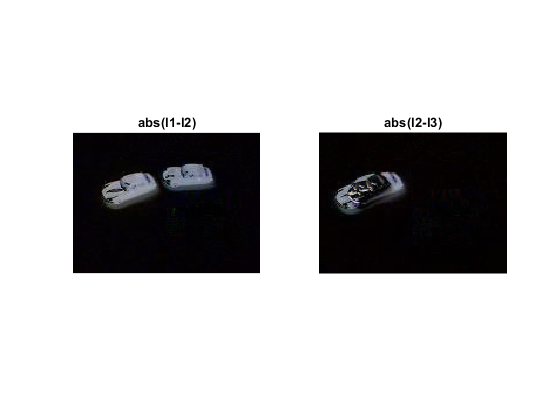

res1 = imabsdiff(I1,I2);
res2 = imabsdiff(I3,I2);
figure, subplot(1,2,1), imshow(res1), title('abs(I1-I2)')
subplot(1,2,2), imshow(res2), title('abs(I2-I3)')

## Imatges amb egomotion

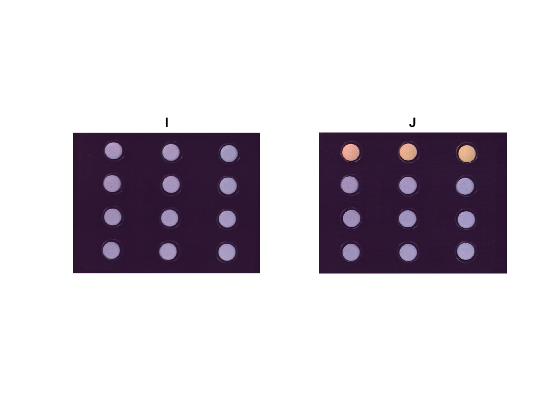

I = imread('Blispac1.tif');
J = imread('Blispac2.tif');
figure, subplot(1,2,1), imshow(I), title('I')
subplot(1,2,2), imshow(J), title('J')

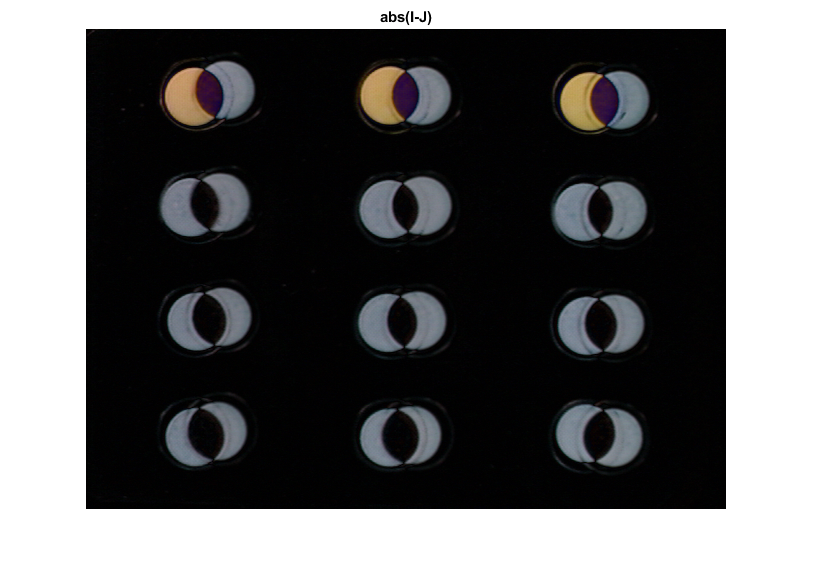

res = imabsdiff(I,J);
figure, imshow(res), title('abs(I-J)')

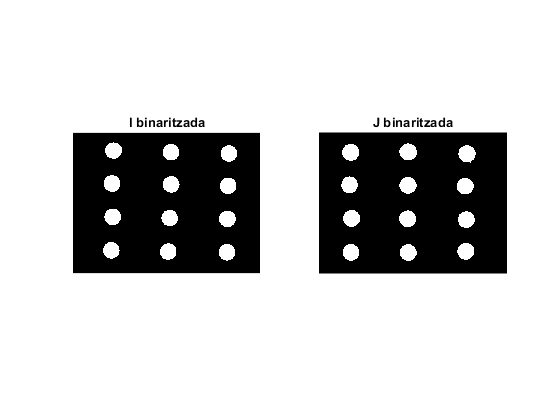

I2 = I(:,:,1);
J2 = J(:,:,1);
BWI = im2bw(I2);
BWJ = im2bw(J2);
figure, subplot(1,2,1), imshow(BWI), title('I binaritzada')
subplot(1,2,2), imshow(BWJ), title('J binaritzada')

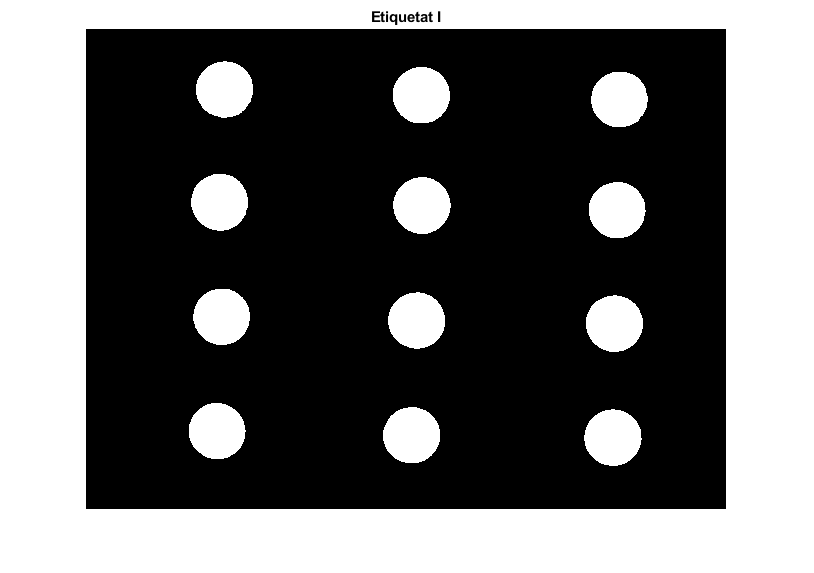


% h = imhist(I2);
% figure,plot(h)
% BW=I2>100;
% figure, imshow(BW)

eti = bwlabel(BWI);
figure, imshow(eti), title('Etiquetat I')

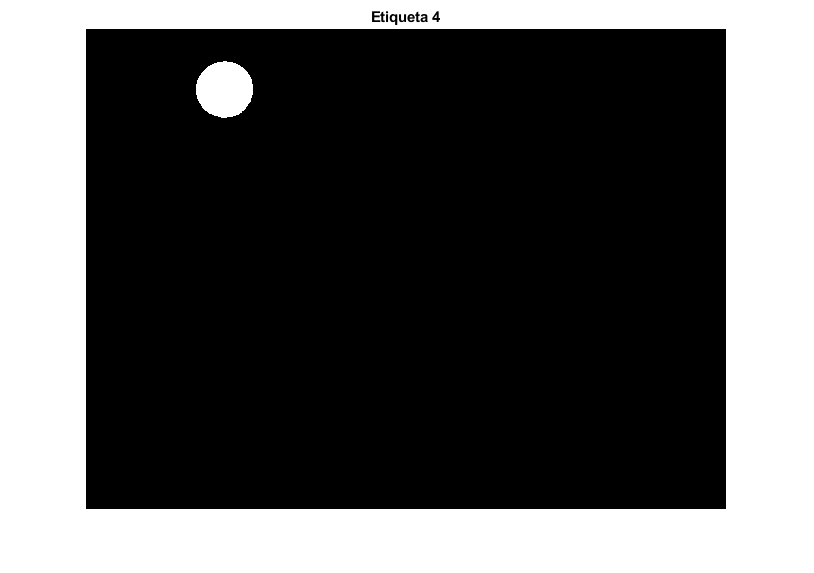

%impixelinfo
aux = eti==4;
figure, imshow(aux),  title('Etiqueta 4')

## Convolucions

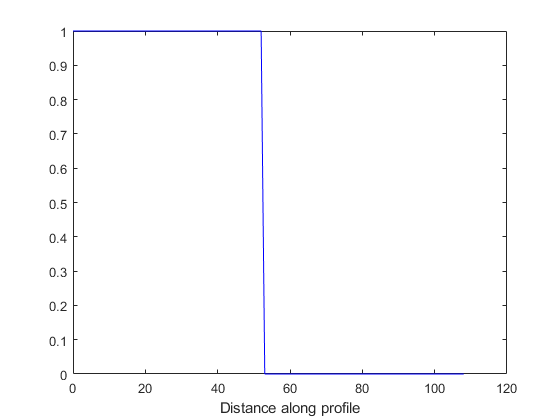

im = ones(256);
im(1:128,1:128)=0;
im(129:256,129:256)=0;
imshow(im), title('Imatge original') 
improfile

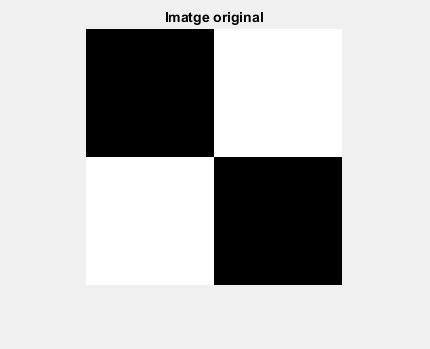

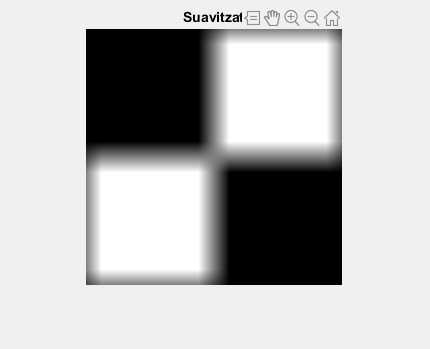

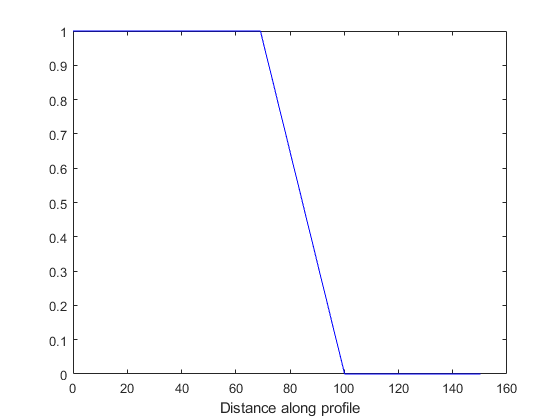

w = ones(31);
res = imfilter(im,w,'conv');
res = res/max(res(:));
figure, imshow(res), title('Suavitzat')
improfile

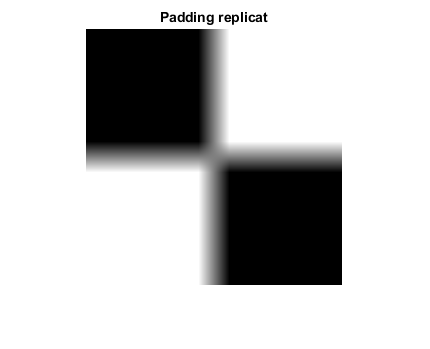

res = imfilter(im,w,'conv','replicate');
res = res/max(res(:));
figure, imshow(res), title('Padding replicat')